# Fundamentals of Image and Video Processing

## Screw Bolt Detection

Let us clear the workspace and read the input image.

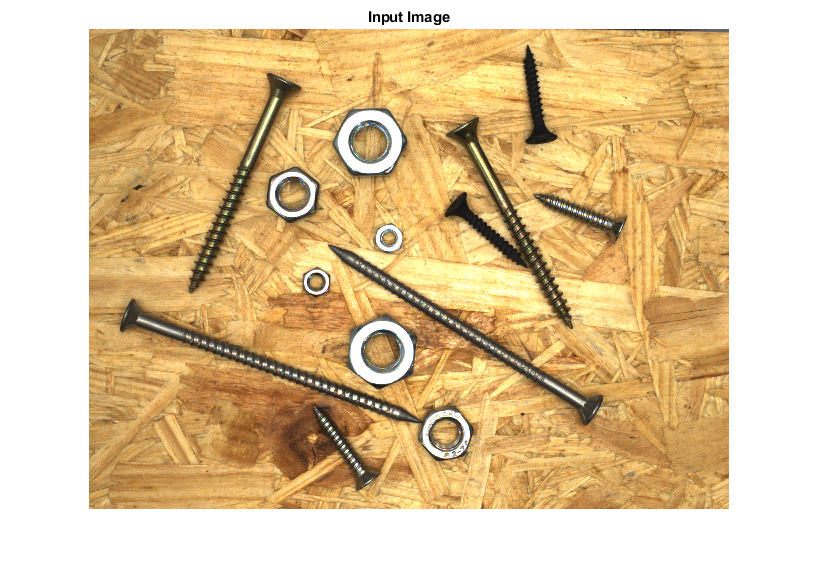

clc;    
clear all;
z=0;
% for z=1:1
%        filename = ['images/screws_'  num2str(z,'%03d') '.png'];
filename = 'images/screws_375.png';
   img = imread(filename);
imshow(img);title('Input Image');

Using Paint Color Picker, 

We concluded that Background consists majority of red colour.

Now,

- filter out Red colour from background

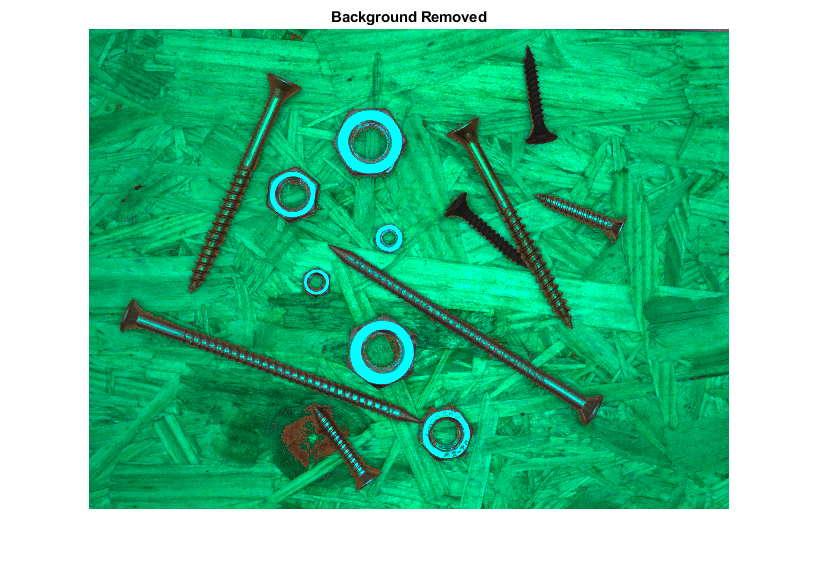

temp = img;
for i=1:1440
    for j=1:1920
        for k = 1:3
        if temp(i,j,1)>120 %Red colour range for background
               temp(i,j,1)= 0;
        end
    end
    end
end
imshow(temp);title('Background Removed');

As top surface of Nut were completely white, we found there Cyan colour.

#### Conclusion: Seperating Cyan part can separate Nuts.

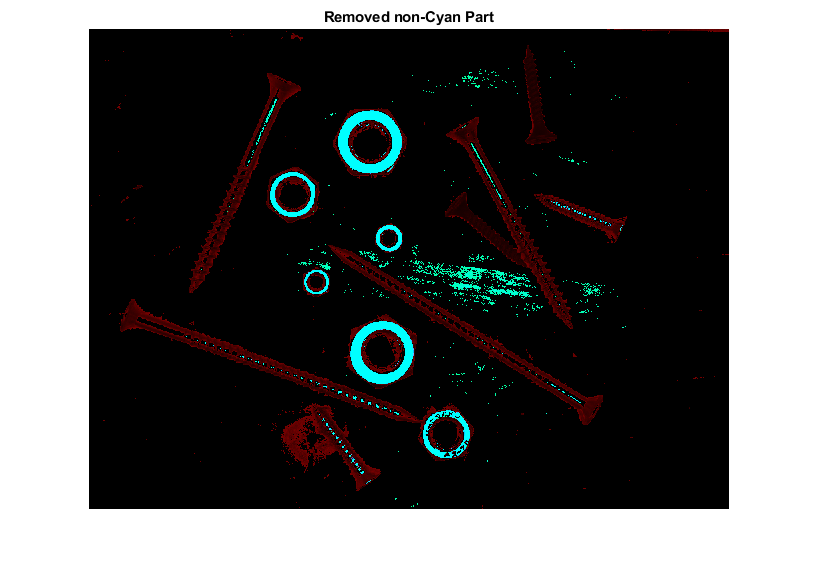

for i=1:1440
    for j=1:1920
        for k = 1:3
         if temp(i,j,2)<255 && temp(i,j,3)<255
            temp(i,j,2)= 0;
            temp(i,j,3)= 0;
       end
    end
    end
end
imshow(temp);title('Removed non-Cyan Part');

To Better visualize and remove Extra parts we white out non cyan part.

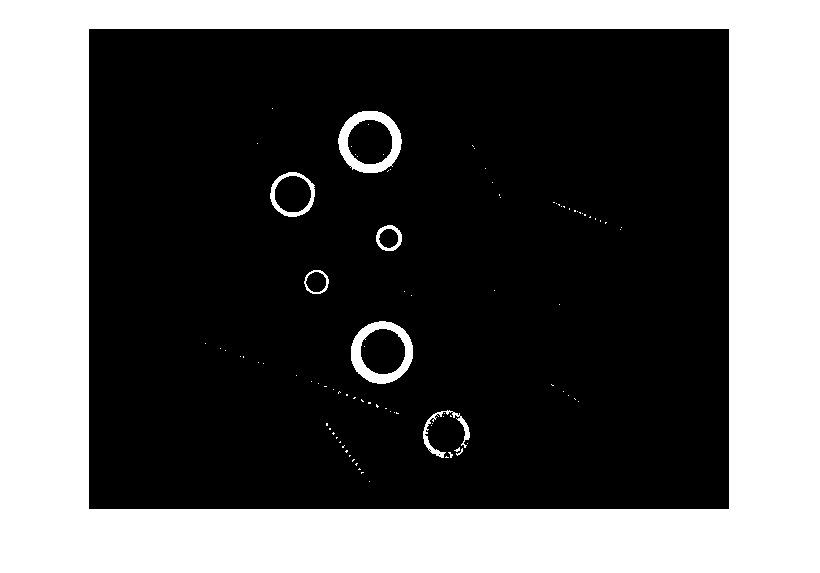

bw = temp;
for i=1:1440
    for j=1:1920
        for k = 1:3
        if bw(i,j,2)==255 && bw(i,j,3)==255 %Red colour range for background
            bw(i,j,1)= 255;
            bw(i,j,2)= 255;
            bw(i,j,3)= 255;
        else
            bw(i,j,k)=0;
        end
        end
    end   
end
imshow(bw);

Now to remove Noise and get clear picture of circle we use different filters.

denoised = bw;
denoised = im2uint8(denoised);
denoised = imgaussfilt(imgaussfilt(denoised));
SE = strel('diamond',[3]);
denoised = imopen(denoised,SE);
imshow(denoised);title('Denoised Image');

 Finding Circles in image.

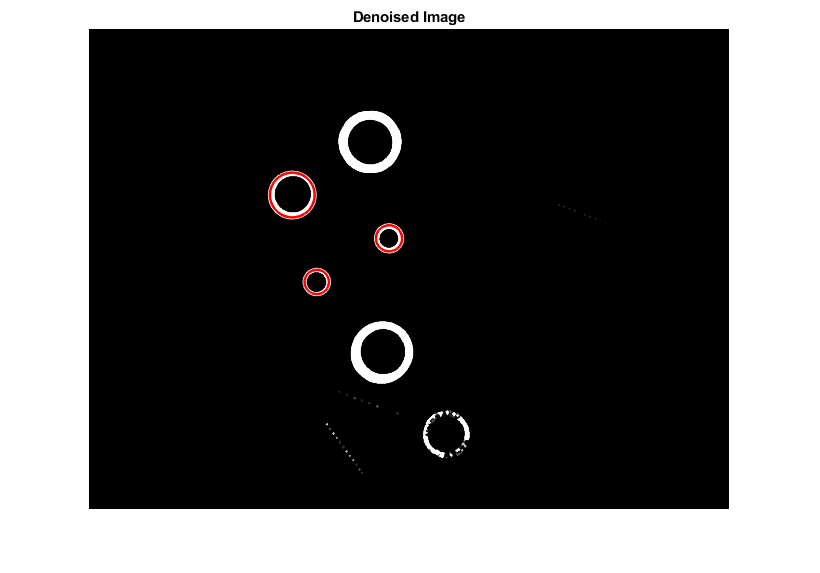

% d = drawline;
% pos = d.Position;
% diffPos = diff(pos);
% diameter = hypot(diffPos(1),diffPos(2))
[centers,radii] = imfindcircles(denoised,[25 ...
    2500 ],'ObjectPolarity','bright','Sensitivity',0.92);
h = viscircles(centers,radii);

Display the positions and dimensions of the nuts.To save the resultant image files in output folder.

disp("We found "+ size(radii,1) + " nuts in given image");

We found 3 nuts in given image


% filename = strcat('results/nuts/result_',num2str(z,'%03d'),'.png');
% imwrite(denoised,filename);
% end

Now we will try to find number of Nuts